# **UNIVERSITAT DE BARCELONA**

# **COMPUTER VISION **

# **LAB 10 REPORT**

## **JORGE ALEXANDER & EMER RODRIGUEZ FORMISANO**

## **9.1**

*Download the code to generate a filter bank of the Derivatives of the Gaussian, in other words: the Leung-Malik (LM) filter bank and display it in a figure:*

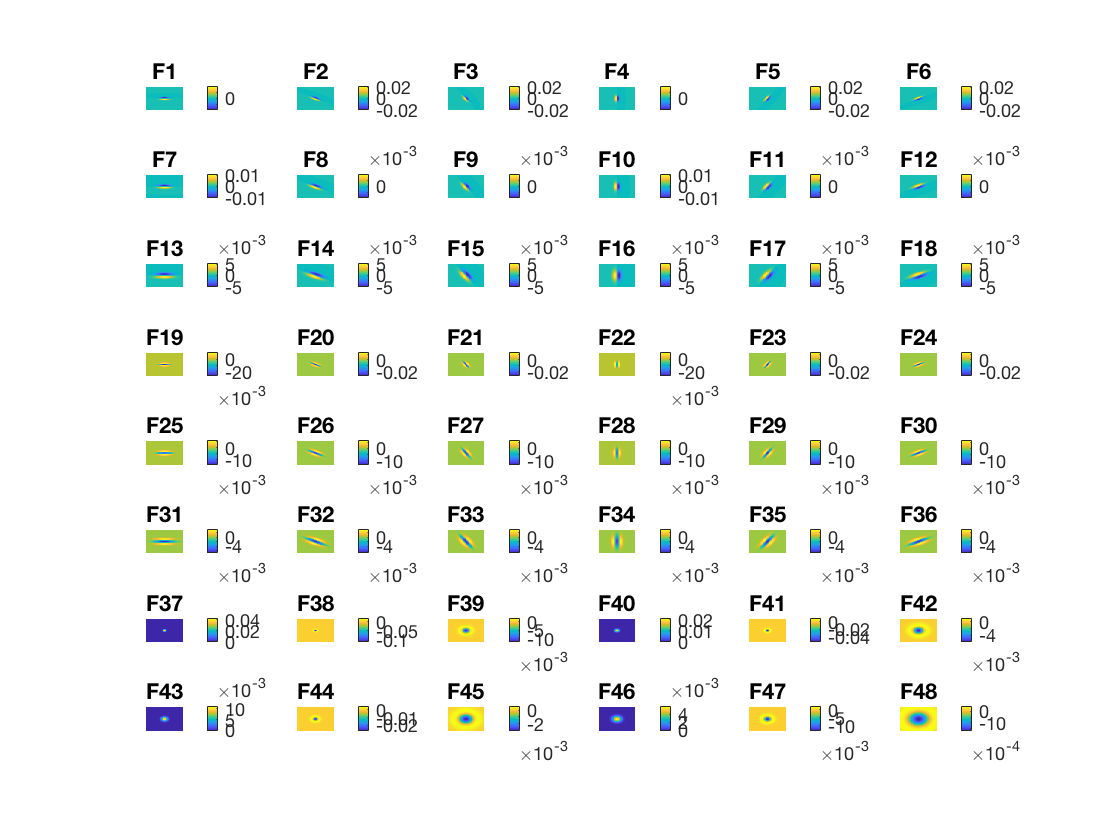

F=makeLMfilters(); % function to generate the filters
visualizeFilters(F);

*Note: Look at the imagesc and colorbar commands. What do they do? What are the different filters? What values do they have?*

`Imagesc` declares the image data that will be used for subplot k. This technique allows simple iterating and display of the different filter images for each subplot.

`Colorbar` simply displays a color scale beside the subplot of the filter image, it displays the current colormap and indicates the scale of the values of the data in the image.

In total there are 48 different edge, bar and spot filters. The first 18 plots correspond to the 6 orientations of the first derivatives of Gaussian edge filter, the next 18 plots correspond to the second derivatives of gaussian bar filters, and the last plots are 8 Laplacian of Gaussian (LOG) spot filters and 4 Gaussian spot filters.

## **9.2**

*Implement a function getFeatures that for an image builds its texture descriptors, where each element of the descriptor is the average result of the convolution of the image with the filters: *

img = imread('texturesimages/buildings/buildings_1.jpg');
[features, convImages]=getFeatures(img);

**(NOTE: the implemented getFeatures() function calculates the mean of the convolution, but does not take the absolute value, this is to be consistent with the figures produced in the exercise description. However, another way to calculate the texture descriptor, explained during the course lectures, uses the absolute value of the convolution, leading to a positive average)**

*How big is the descriptor? *

size(features)

ans =      1    48


The feature descriptor has 48 columns in size, each corresponding to the mean convolution value of the image processed by a different filter.

*When looking at the texture of the image, we will not consider the colour at this stage. Therefore, you must convert the colour image to grayscale. *

*Display the result of the convolution with the filters: *

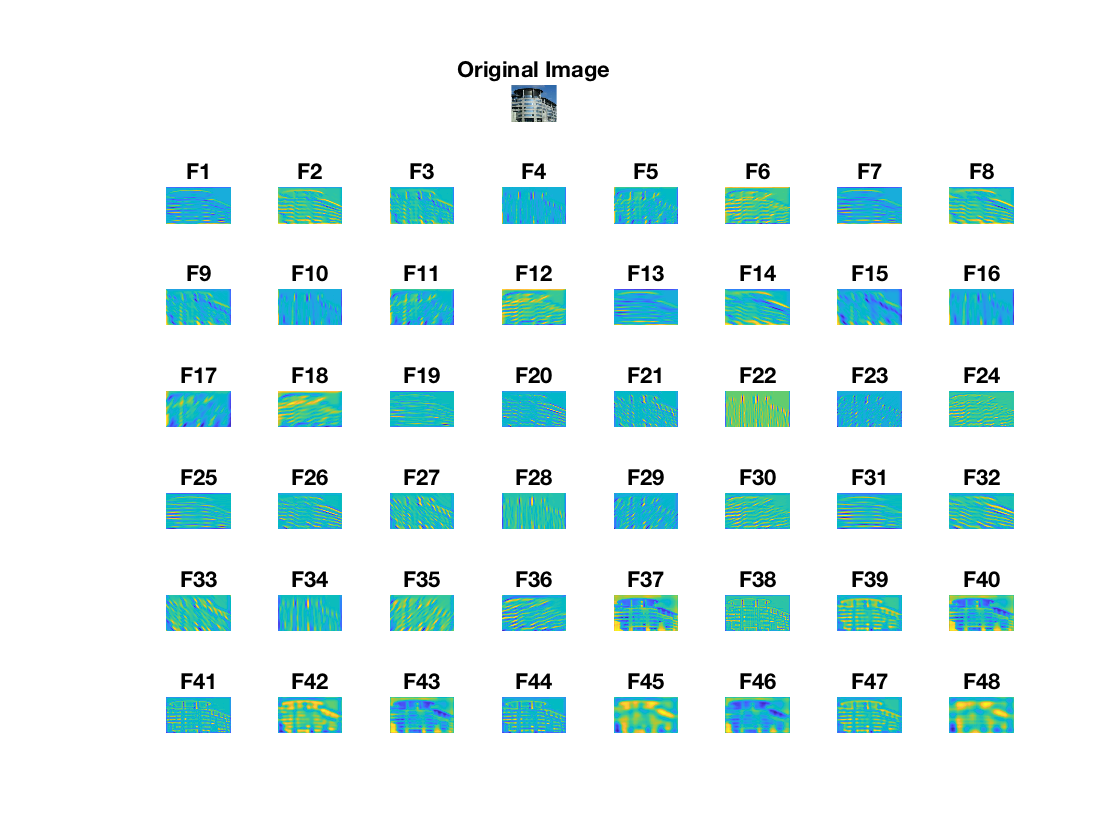

clf();
clear title xlabel ylabel;
figure(3);
plotRows=7;
plotCols=8;
subplot(plotRows, plotCols, 4); imshow(img); title('Original Image'); 
for i=1:length(convImages)
    subplot(plotRows, ceil(plotCols), i+plotCols); 
    imagesc(convImages{i}); axis off; title(strcat('F', num2str(i)));
end 

*Observe which filters have a better response on the image you have chosen and discuss why:*

It is observed that the filters with a horizontal or slightly slanted orientation have a high response to the image used. For example, filter F14. This is because the image, which shows a building, has several prominent horizontal lines showing, as well as slanted edges such as the alignment of the windows and roof.

## **9.3**

*Write a getClassFeatures function that given a directory and an extension, read all images in the directory with the extension given, calculates their texture descriptors (using getFeatures of 9.1.2) and stores them in a matrix where each row corresponds to an image and each column to a feature. Apply this to build three matrices of texture descriptors corresponding to the 3 image directories.      *

buildings = getClassFeatures('texturesimages/buildings','jpg');
forest = getClassFeatures('texturesimages/forest','jpg');
sunset = getClassFeatures('texturesimages/sunset','jpg');

*Note: The way to access the i-th file in the directory will be through files(i).name. Check what makes fullfile: *

fullfile is a matlab function that takes file-parts as arguments and joins them in order to build a full file specification, appropriate to the operating system being used.

## **9.4**

*Write a visualizeFeatures function to display in a plot a list of one or several features (eg [25, 41]) for images of the three directories using a different color for each directory (help plot). Define another function visualizeFeatures3D to display as 3D plots the three groups of images (corresponding to the 3 directories) using three specific features (eg. [25, 38, 41]):*

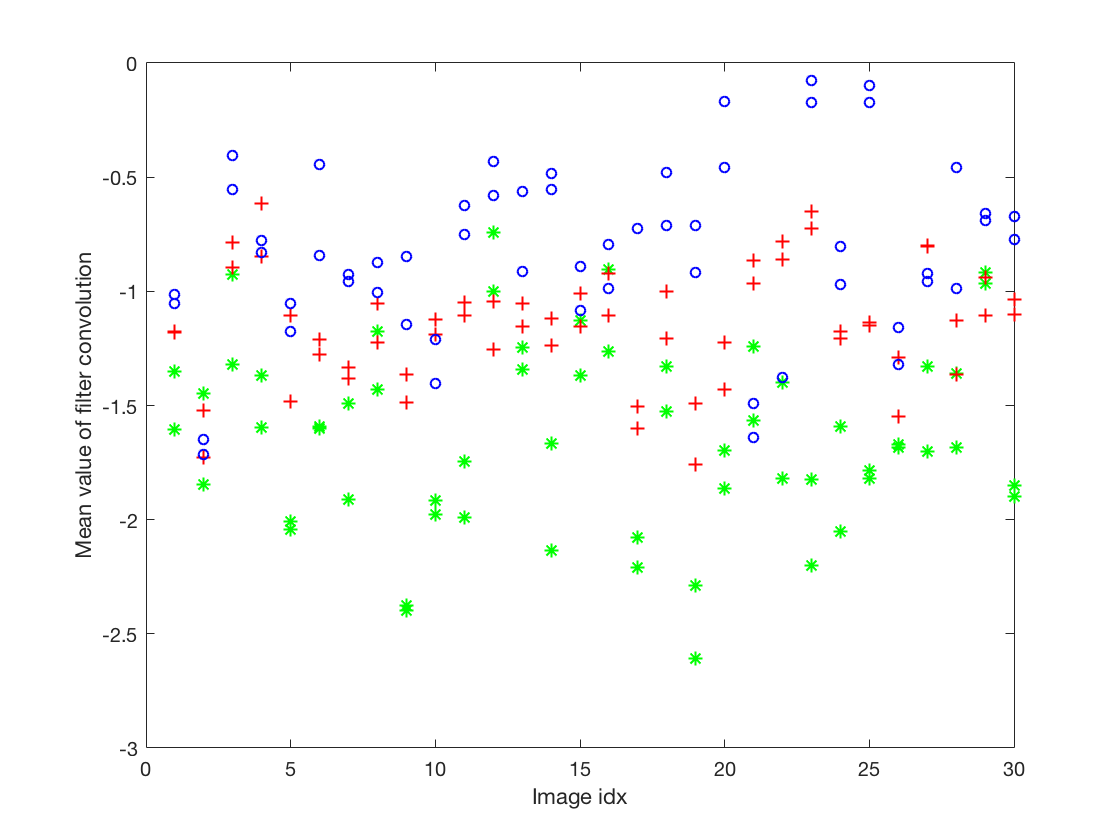

visualizeFeatures({buildings,forest,sunset}, {'g*','r+','bo'}, [41,25]);

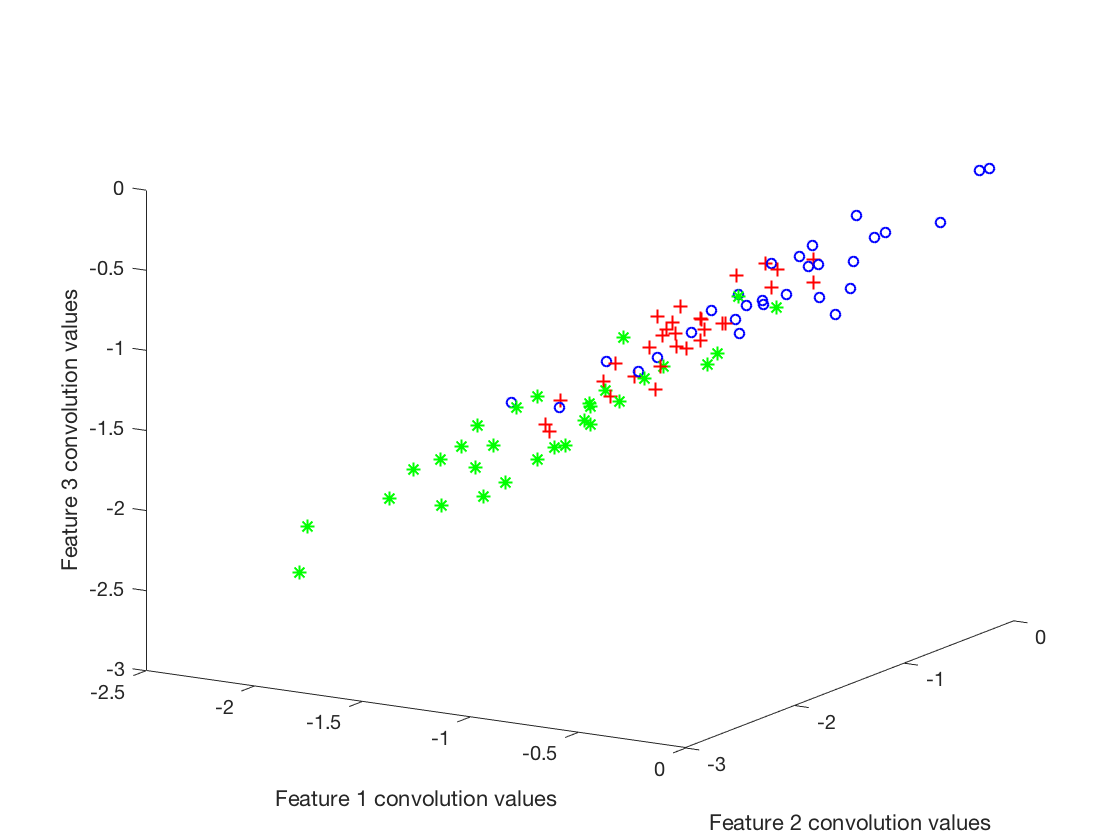

visualizeFeatures3D({buildings,forest,sunset}, {'g*','r+','bo'}, [25,38,41]);

view([31.30 17.20])

*What does each axis correspond to in the 2D and 3D visualizations?*

In the 2D visualization, the x axis corresponds to the image number, and the y axis corresponds to the average of the convolution with a filter.

In the 3D visualization, each axis represents the convolution values of a different feature. In this case the x axis represents image 25's convolution values, y axis image 38's and the z axis image 41's.

## **9.5**

*For each image of the three classes, write the function  retrieveKImages to retrieve and display the k (e.g. k = 9) most similar images as texture descriptors  (see Fig. 4).  Note: You can use the command knnsearch:*  

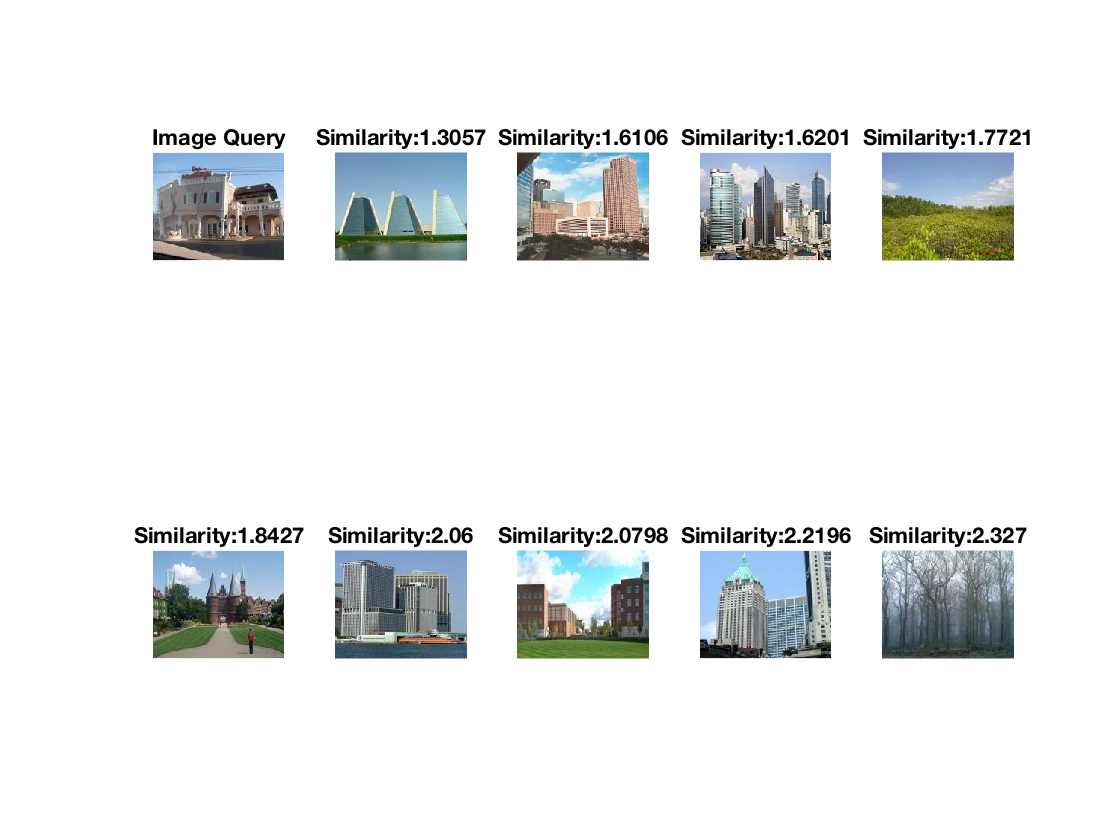

images = retrieveKImages(7,...
    {'texturesimages/buildings', 'texturesimages/sunset', 'texturesimages/forest'},...
    'jpg', 9, false);

*Observe the result when the colour (r, g, b) is added to the texture features as additional features per image:*

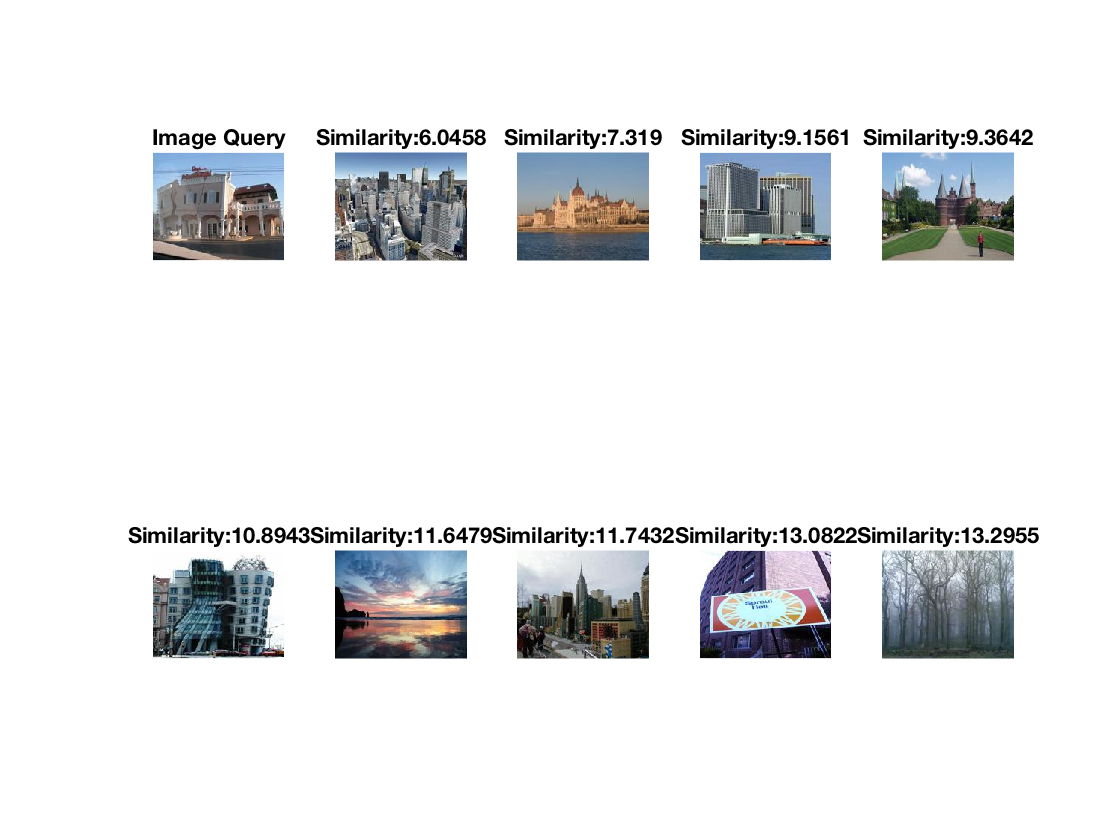

images = retrieveKImages(7,... 
    {'texturesimages/buildings', 'texturesimages/sunset', 'texturesimages/forest'},... 
    'jpg', 9, true);

*What dimension will the feature space have if we add the colour? *

The feature space now has three extra features, R, G & B. R corresponds to the mean value of the red layer of the image, G corresponds to the mean value of the green layer, and B corresponds to the mean value of the blue layer. The calculation can be found in the "getColorFeatures.m" script.

*Observe what are the most discriminative features for each set of images first without using colour and after adding colour features. Discuss your observations on the performance of the algorithm and possible improvements.*

It is observed that without the color, using euclidean distance knn, the similarities are much closer than when color is added. Also, when the color is added, the similar images are different, as the color now means that previously similar images are not so similar. Perhaps to improve the algorithm, images could be ranked on similarity based on their average similarity rank across different metrics. For example, apart from using color and greyscale, using different knn distance measures such as the cosine distance. 